clear all
clc

## 1) Loading, preparing and plotting the data:

% a) loading the dataset
%data = load("D:\HAN Sem 2\Term 2\BDSD System Identification\Applied System Identification Assignment May 2024\evaporator.dat\evaporator.dat");
load("evaporator_dataset.mat")

% b) creating identification data object
input_data = data(:, 1:3); % first three colums being the inputs
output_data = data(:, 4:6); % rest of the three columns being the outputs
Ts = 0.5; % assuming a sampling time  

data_id = iddata(output_data, input_data, Ts);
%get(data_id)

% c) labelling the inputs and outputs
data_id.InputName = {'Flow of feed product', 'Flow of vapor', 'Flow of cooling water'};
data_id.OutputName = {'Dry matter content', 'Flow of outcoming product', 'Temperature of outcoming product'};

get(data_id)

ans = struct with fields:
              Domain: 'Time'
                Name: ''
          OutputData: [6305×3 double]
                   y: 'Same as OutputData'
          OutputName: {3×1 cell}
          OutputUnit: {3×1 cell}
           InputData: [6305×3 double]
                   u: 'Same as InputData'
           InputName: {3×1 cell}
           InputUnit: {3×1 cell}
              Period: [3×1 double]
         InterSample: {3×1 cell}
                  Ts: 0.5000
              Tstart: 0.5000
    SamplingInstants: [6305×1 double]
            TimeUnit: 'seconds'
      ExperimentName: 'Exp1'
               Notes: {}
            UserData: []


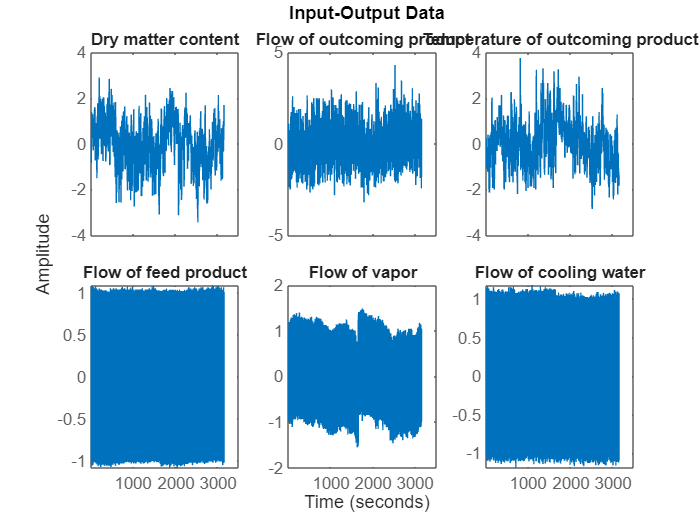

% d) plotting
figure;
plot(data_id);

% e) splitting the dataset into identification and validation subsets
N = length(data_id.y);
data_id_train = data_id(1:floor(N/2));
data_id_val = data_id(floor(N/2)+1:end);

In the above section the data was imported, identification data object was created, the inputs and outputs were labelled and plotted and finally the data was split into half of the data for identification and the rest half for validation subsets.

## 2) Estimating an impulse response model 

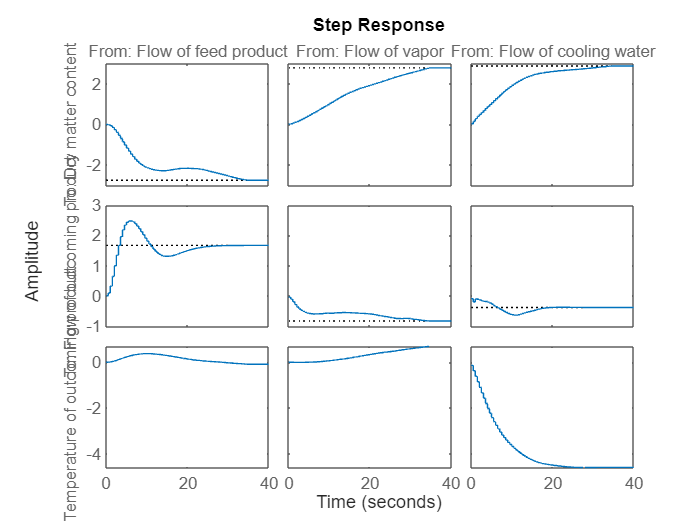

% a) estimate impulse response model
impulse_model = impulseest(data_id_train);

% b) plot the step response of the impulse model
figure;
step(impulse_model);

c) The step response plots align well with the physics of an evaporator. The reasons for this conclusion are as below:

1) For the input - Flow of feed product:

- An increase in feed product flow decreases the dry matter content due to dilution and eventuually stabilizes. This makes sense because the increase in flow of feed product would reduce the concentration of solids until the system reaches a new equilibrium. 

- The increase in feed flow initially increases the outgoing flow rate with some oscillation with an overshoot and shows the system's attempt to balance the inflow and outflow rates. 

- Theres a slight decrease in temperature as feed product absorbs heat initially leading to the temperature drop before stabilization.

2) For the input - Flow of Vapor:

- Increase in vapour flow shows increase in dry matter content, this makes sense because more the water is evaporated more the concentration of solids increases. 

3) For the input - Flow of cooling water:

- Increase in cooling water flow increases the dry matter content because better cooling results in more condensation and seperation of vapour from the product. 

- Theres a decrease in outgoing product flow, because of better cooling better condensation and seperation of water vapour is achieved which reduces the liquid phase in the outgoing product. 

- A significant and rapid decrease in temperature is observed in this plot. The flow of cooling water lowers the tenperature of the product and condenses the vapour, which is its main purpose. 

In conclusion the relationships between inputs and outputs observed in the plots reflect expected physical phenomena such as dilution, evaporation and heat exchange which confirms the data's physical sense. 

## 3) Feedthrough 

a) In an evaporator, an increase in the feed product flow rate can immediately change the flow rate of the outgoing product. This is also visible in the impulse response plots.

The concentration of dry matter is a direct result of the amount of water removed in the form of vapour. The faster the vapour is generated and removed, the quicker the dry matter content changes, suggesting a direct effect. This can be seen in the impulse response plots where the increase in the flow of vapour immediately increases the amount of dry matter. 

The cooling water can directly affect the product temperature as soon as it enters the evaporator. This can be seen in the impulse response plots as well, as the cooling water increases the temperature of the product immediately decreases.

Based on the above given analysis the presence of direct feedthrough effects in the evaporator system justifies a nonzero D matrix.

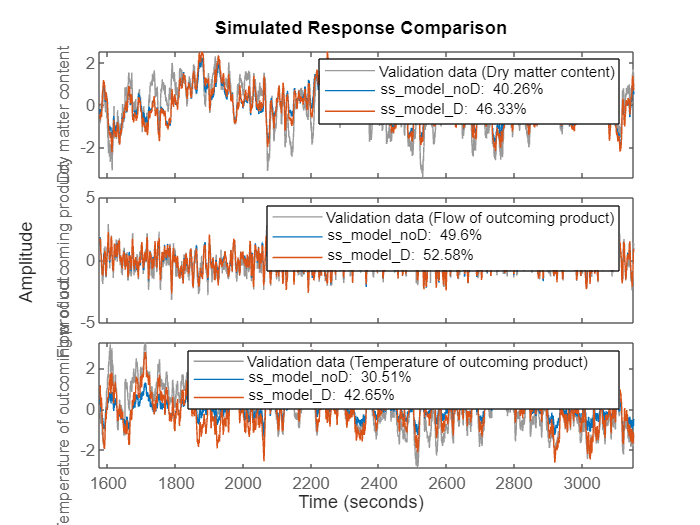


% b) identifying continous time statespace models with and without feedthrough

order = 4; % assuming an order

% without feedthrough
ss_model_noD = ssest(data_id_train, order, 'Feedthrough', false);

% with feedthrough
ss_model_D = ssest(data_id_train, order, 'Feedthrough', true);

% plotting both
figure;
compare(data_id_val, ss_model_noD, ss_model_D);

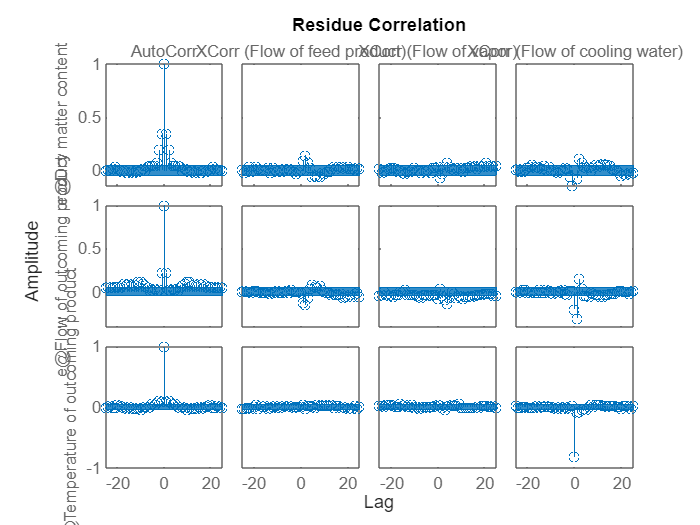

% residuals analysis
figure;
resid(data_id_val, ss_model_noD);

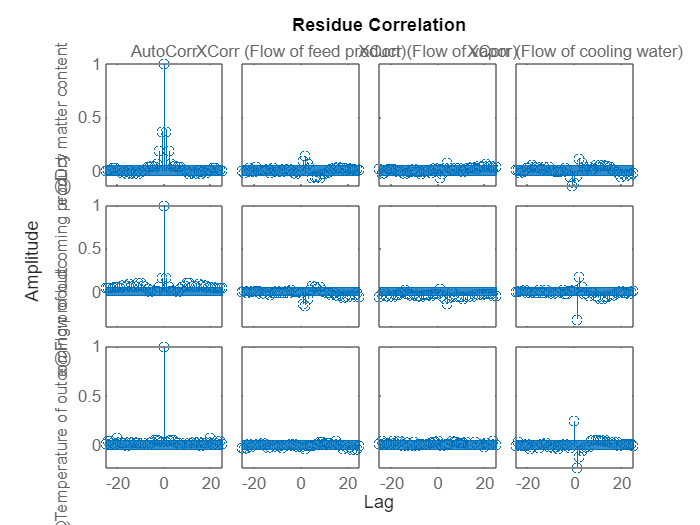

figure;
resid(data_id_val, ss_model_D);

From the plot of the simulated response comparison it can be observed that:

- Including feedthrough improves the model fit by approximately 6%, suggesting that the direct effect of inputs on outputs is significant for dry matter content. 

- The model fit improves by about 3% when feedthrough is included, indicating that the direct effect of inputs on outputs play a role in predicting the flow of the outgoing product.

- The model fit improves significantly by approximately 12% with feedthrough included, indicating a strong direct effect of inputs on the temperature of the outgoing product. 

From both the residue correlation plots it can be observed that there are some minor peaks in the cross-correlation plots between residuals and inputs which indicate direct effects that are not fully captured by the model. These peaks, are observed in both the models, this indicates that some direct effects remain unmodelled even when feedthrough is included.

But in conclusion it is clear from the response comparison plots that including feedthrough imporves the model accuracy.

## 4) Discrete time state space model 

% a) determining the best three model orders 
ss_models = n4sid(data_id_train,2:50, 'Ts', Ts);

Here model orders from 2 to 50 are analysed. In the generated plot the vertical axis 'log of singular values' is a relative measure of how much each state contributes to the input/output behavior of the model and the horizontal axis corresponds to the model order n. The plot recommends order = 8, indicated by a red rectangle, and by looking at the plot, 7th and 9th order are also good fits with less and more model complexity respectively and possibly offering approximately the same performance therefore the best three orders chosen are 7,8 and 9. 

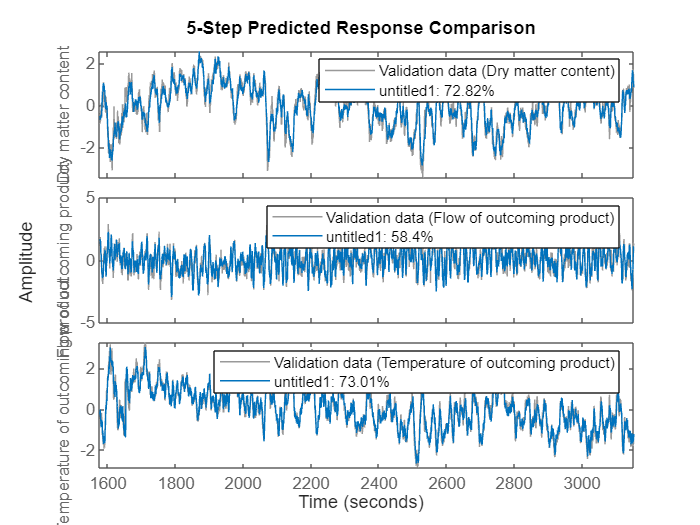

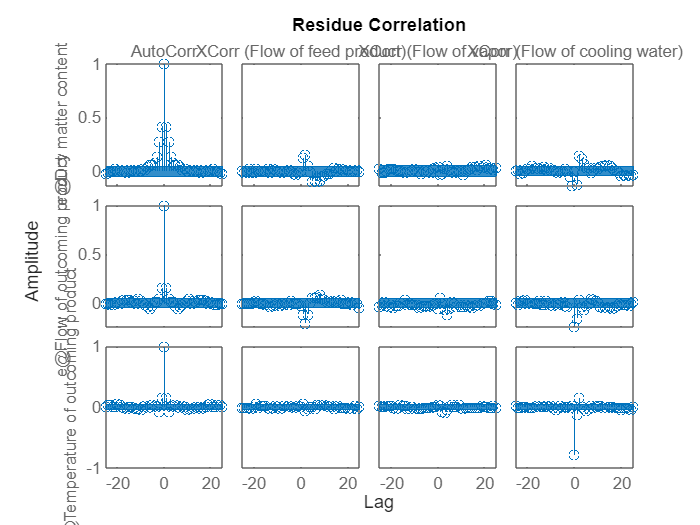

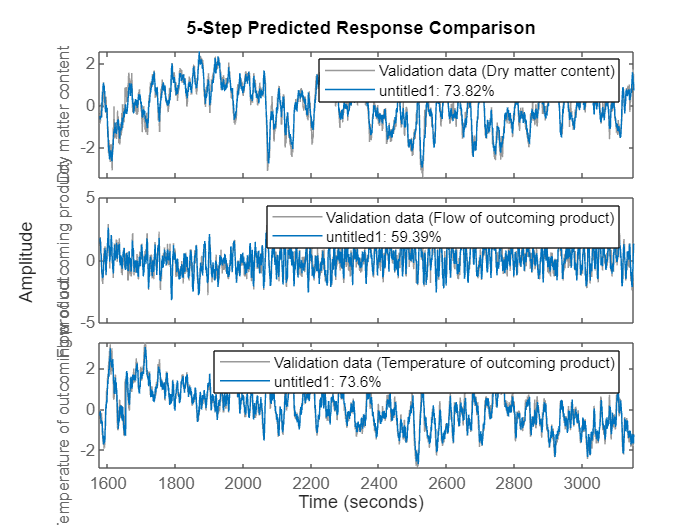

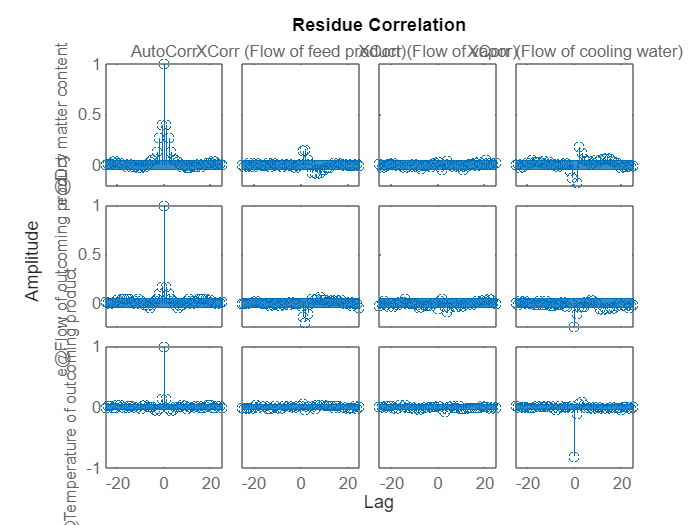

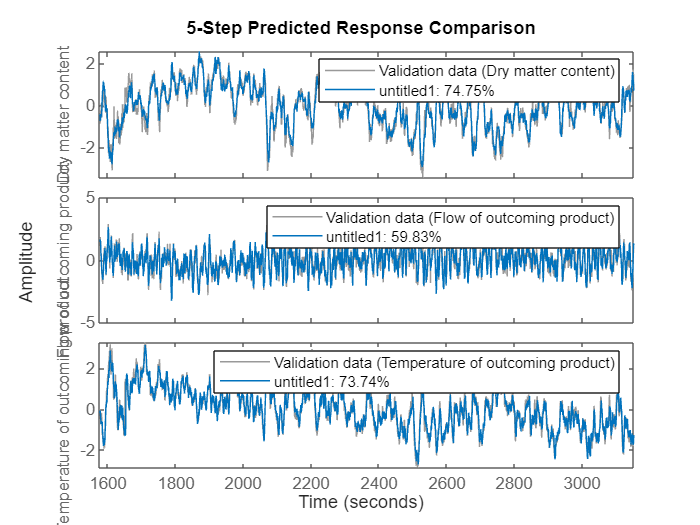

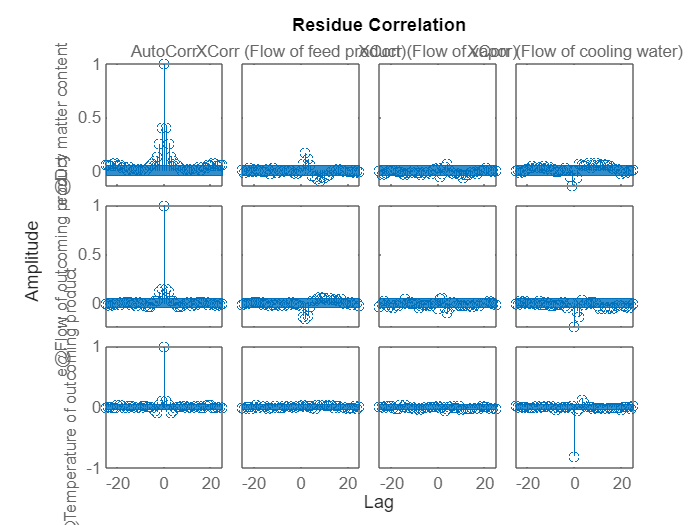


%  b) three discrete time state space models
orders = [7, 8, 9];
% discrete time state space models
ss_models = cell(1, length(orders));
for i = 1:length(orders)
    ss_models{i} = n4sid(data_id_train, orders(i), 'Ts', Ts);
end

% c) validating models in terms of 5 step ahead prediciton 

for i = 1:length(ss_models)
    figure;
    compare(data_id_val, ss_models{i}, 5); % 5 step ahead prediction
    figure;
    resid(data_id_val, ss_models{i});
end

d) It can be observed from the response comparison plots that the higher the order of the model the better the fit. 

From the chosen three orders the fit for order =  9 for dry matter content is 74.75% accurate, 59.83% for flow of outcoming product and 73.74% for temperature of outcoming product. This is the highest from the three chosen orders. But for order = 8 the predicitons are 73.82%, 59.39% and 73.6% accurate for each output respectively. The predictions for 8th and 9th order are very close.

And analysing the residual correlation plots, for model order 7 there is significant autocorrelation and cross correlation, indicating that it may not be fully capturing the system dynamics. For model order 8 there is slightly improved residual behaviour compared to model order 7, wiht reduced autocorrelation and fewer cross correlations. Model order 9 shows almost similar residual behaviour to model order 8, except in certain plots where more cross correlation can be observed. 

Since the model needs to be implemented on an MPC controller, where the model complexity should also be kept in mind the model with order = 8 can be chosen for the final controller design and implementation because of its optimal performance among the three chosen orders based on analysing performance comparison plots and residual analysis .